% Einlesen des Testspektrums
identPath ="G:\Meine Ablage\Master\02_research\Masterarbeit\04_Daten\Test_ML\LDPE_PET_Folie_Platte_glatt_ML.csv";
identData = readmatrix(identPath, 'Delimiter', ';');
data = identData(:,2);

integral_values = zeros(1, length(filter_regions));

% Daten für den aktuellen Durchlauf
all_x_data= wavelengths;
all_y_data = data;

% Funktion erstellen durch Interpolation
interp_function = @(x) interp1(all_x_data, all_y_data, x, 'linear', 'extrap');
% Berechnung des Integrals fuer jeden Bereich
for j = 1:length(filter_regions)
    fun = interp_function;
    integral_values(:,j) = integral(fun, filter_regions(j,1), filter_regions(j,2));
end

tic
% Normierung und Transformation des unbekannten Spektrums
centeredUnknownSpectrum = zscore(integral_values);
unknown_point = centeredUnknownSpectrum * coeff(:, 1:3);

% Toleranzen der einzelnen Materialien
tol = [0.02,0.01,0.03,0.01,0.01];

tic
% Ueberpruefung ob und wenn ja in welcher Huellkurve die Testdaten liegen
for i = 1:5
    AT = T{i};
    hull = {AT.Points(:, 1), AT.Points(:, 2), AT.Points(:, 3)};
    conHull = cell2mat(hull);   
    in = inhull(unknown_point, conHull, [], tol(i));  
    if in == 1
        i
        break; % Beende die Schleife, wenn in gleich 1 ist
    end

end
toc

Elapsed time is 0.005823 seconds.


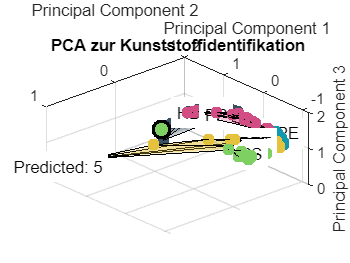


% Plotten der Ergebnisse
figure;
grid on;
hold on;

classLabels = {'HDPE', 'LDPE', 'PET', 'PP', 'PS'};
for label = 1:5
        idx = (y == label);
        text(mean(X_pca(idx, 1)), mean(X_pca(idx, 2)), mean(X_pca(idx, 3)), classLabels{label}, ...
            'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1], 'EdgeColor', [1 1 1]);
       
        DT = T{label};
        convHull{label} = convexHull(DT);
        K = convHull{label};
        
        color = [ 0.2235294117647059  0.3137254901960784 0.38823529411764707
            0.07058823529411765  0.596078431372549  0.6784313725490196
            0.8941176470588236  0.7607843137254902  0.23921568627450981
            0.8196078431372549  0.30196078431372547  0.5137254901960784
            0.49019607843137253  0.8156862745098039  0.3803921568627451
        ];
        color = color(label, :); % Auswahl der Farbe fuer das aktuelle Label
        
        % Plotten der konvexen Huelle für die aktuelle Klasse mit entsprechender Farbe
        trisurf(K, DT.Points(:, 1), DT.Points(:, 2), DT.Points(:, 3), ...
            'FaceColor', color, 'FaceAlpha', 0.3, 'EdgeColor', 'k');
        scatter3(X_pca(idx, 1), X_pca(idx, 2), X_pca(idx, 3), 50, color,  'filled');
end
color = [ 0.2235294117647059  0.3137254901960784 0.38823529411764707
            0.07058823529411765  0.596078431372549  0.6784313725490196
            0.8941176470588236  0.7607843137254902  0.23921568627450981
            0.8196078431372549  0.30196078431372547  0.5137254901960784
            0.49019607843137253  0.8156862745098039  0.3803921568627451
        ];
% Plotten des unbekannten Spektrums im Hauptkomponentenraum
color_unknown = color(i,:);
scatter3(unknown_point(1), unknown_point(2), unknown_point(3), 100, color_unknown, 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 2);

% Textlabels der einzelnen Materialien
classLabels = {'HDPE', 'LDPE', 'PET', 'PP', 'PS'};
for label = 1:5
    idx = (y == label);
    text(mean(X_pca(idx, 1)), mean(X_pca(idx, 2)), mean(X_pca(idx, 3)), classLabels{label}, ...
        'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1], 'EdgeColor', [1 1 1]);
end

% Textlabel mit dem vorhergesagten Material
text(unknown_point(1), unknown_point(2) + 1.5, unknown_point(3), ['Predicted: ', num2str(i)], ...
    'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1], 'EdgeColor', [1 1 1]);

% Diagrammanpassungen
view(48, 134);
title('PCA zur Kunststoffidentifikation');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');